# Activity Flow in DEM_demo_induced_fMRI.m

The purpose of this notebook is to clarify how activity spreads in the network across time when using code inspired by `DEM_demo_induced_fMRI.m` which generates "resting state" data from an AR(1) process. I'll focus on the (unobserved) neural states x. The data analysis happens at the observable BOLD level which is generated by applying the balloon model to the neural states x. The parameters for the conversion from neural states to BOLD timeseries are set and not changed by us in our simulations. Our changes to the true connectivity matrix A or the input effect matrix C only affect neural state propagation. 

## Order of operation

`DEM_demo_induced_fMRI.m` --> `spm_int_J.m` --> `spm_fx_fmri.m`

`DEM_demo_induced_fMRI.m` sets the parameters

`spm_int_J.m` loops through the time points and integrates the states using the state equation described in 

`spm_fx_fmri.m` describes how states change for each time point given the current state, the network structure and the input.

## The AR(1) process

This determines the input `u` and the observation noise `e` in `DEM_demo_induced_fMRI.m`. The third argument to the function `spm_rand_mar.m `determines the AR(p) coefficients and its lenght determines the `p` for AR(p), i.e. how much of the previous time steps is incorporated into the current time step.

In our simulations this can be controlled by `stim_options.ar_coef` where the default is set to 0.5.

How does activity look like for different values of the AR coefficient?

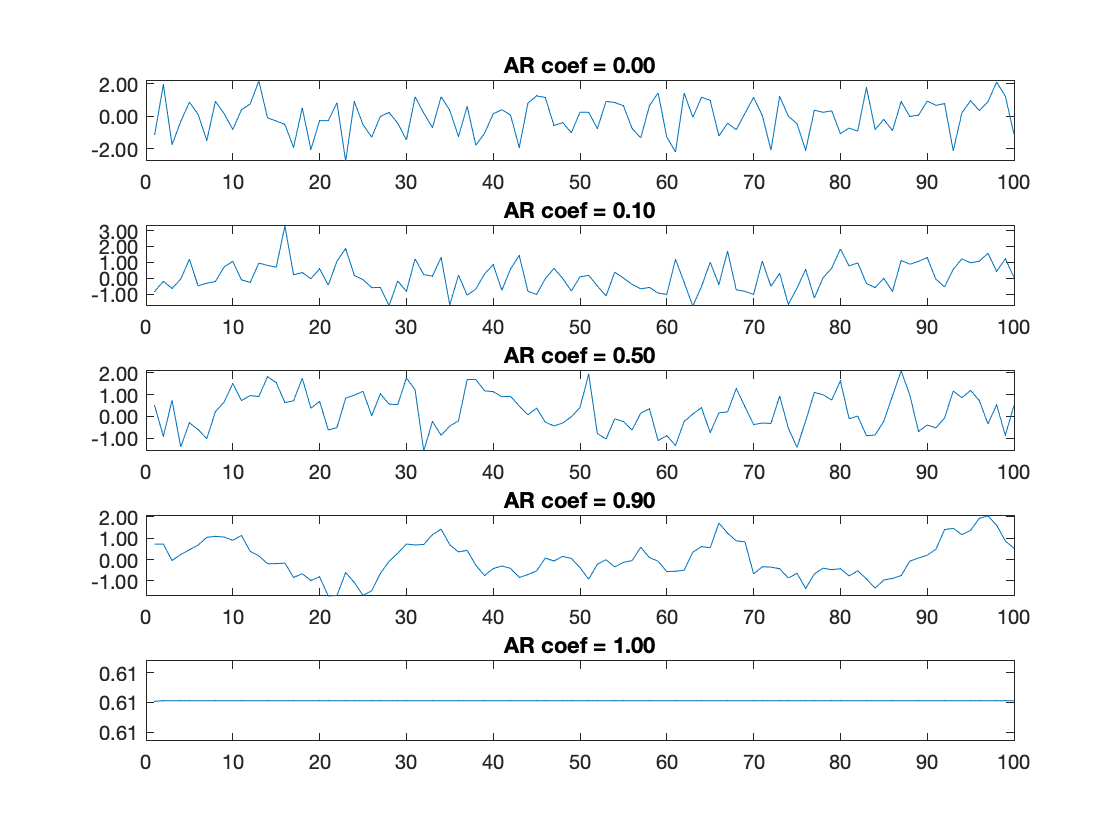

ar_coefs = [0 .1 .5 .9  1];
for i = 1:length(ar_coefs)
    tmp = spm_rand_mar(100,1,ar_coefs(i));
    subplot(length(ar_coefs), 1, i);
    plot(tmp);
    title(sprintf("AR coef = %.2f", ar_coefs(i)))
    ytickformat('%.2f')
end

## Activity flow

This is a function of EE, the curent neural state x, the C matrix that describes how each input affects each node and the input vector u(t).

How does this connect to the Cole et al. framework?